# 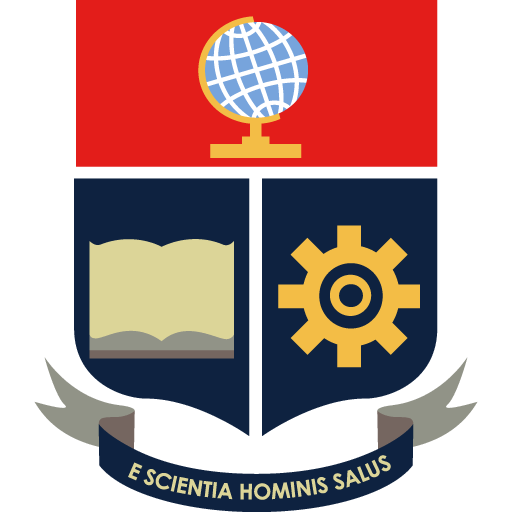Escuela Politécnica Nacional

#### `UTILIZACIÓN DEL SISTEMA DE RECONOCIMIENTO DE GESTOS EMPLEADO EN EL PROYECTO DE INVESTIGACIÓN PIGR-19-07 PARA EL COMANDO DE UN SISTEMA MULTI-AGENTE`

# **Inicialización y Conexión**

`La inicialización de las variables del sistema y conexión inicial a ROS se realizan una vez cada sesión`

clear all;
clc;

% Datos iniciales
t_sim=600;
form=1;
ant=0;
antd=0;
antop=0;
aux=0;
option=6;gesim="6.png";gesto="Relajado - No Gesture";
d=0.5;
PosX1=0.5;
PosY1=0.5;
PosX2=0;
PosY2=1;
PosX3=-0.5;
PosY3=0;
x=0;%Pos incial del lider virtual
y=0;
rx1=PosX1; ry1=PosY1;%Pos inicial de los agentes referenciados en el lider virtual
rx2=PosX2; ry2=PosY2;
rx3=PosX3; ry3=PosY3;
mssg="Seleccionar modo";
ind=1;
ind2=1;
niv=1;
nivel="Control de formación";
 
%PosX1(length(PosX1))--indica que toma el ultimo valor del vector, lo
%que significa que es la posicion actual

### `Conexión a ROS MASTER`

- Abrir la escena en la máquina virtual **ROS Noetic Foxy Gazebo v11**

- Seleccionar el tipo de escena que se abrió

- Conectar

rosshutdown
setenv('ROS_MASTER_URI','http://192.168.174.129:11311')
% rosinit
gazeboIP='192.168.174.129';
rosinit(gazeboIP);

Initializing global node /matlab_global_node_34491 with NodeURI http://192.168.174.1:52881/


%Servidor abierto a cualquiera en el puerto 3000 ("0.0.0.0")
server = tcpserver("0.0.0.0",3000);
% server2 = tcpserver("0.0.0.0",3100);


a=1;
escena=2;
if escena==1
    sim("OneRobot.slx");
elseif escena==2
    sim("Inicialization.slx");
end
rx1=PosX1; ry1=PosY1;%Pos inicial de los agentes referenciados en el lider virtual
rx2=PosX2; ry2=PosY2;
rx3=PosX3; ry3=PosY3;

 

`Si desea cambiar su selección:`

 
if escena==1
    open("prueba1.mlx")
elseif escena==2
    open("menu.mlx")
end

function printStatus (mssg)
     if ind == 1
         % The very first time we don't need to delete the old text
         fprintf('Nivel seleccionado: %s', mssg);
     else
        % Each \b removes one character from the previous fprintf.
        fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bNivel seleccionado: %19s', mssg);
     end
end